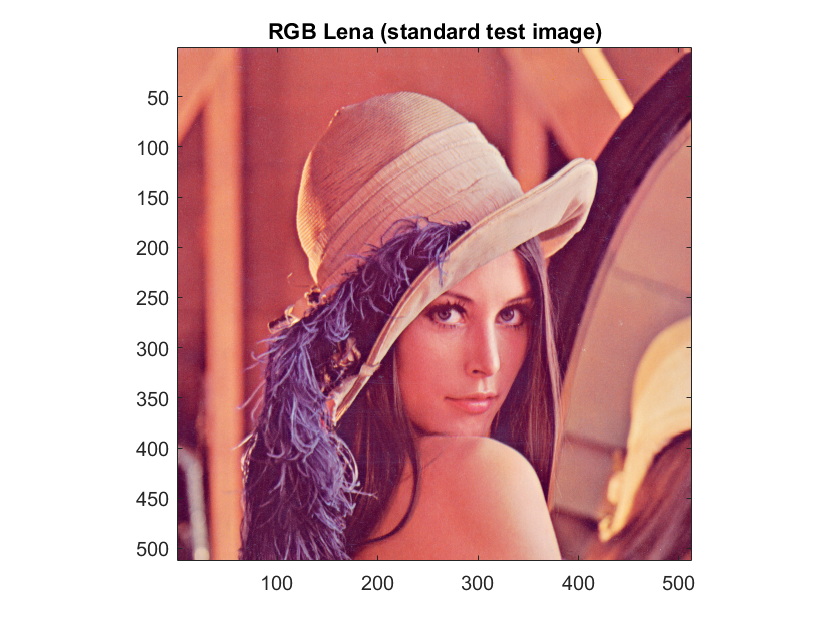

%RGB image 
A = imread('Lena.bmp'); % Read a 24-bit color image (8 bits x 3 channels)
figure;
image(A);               % Display an RGB image(RGB: Red, Green, Bleu)
axis image;             % Set axis to image aspect ratio
title('RGB Lena (standard test image)');

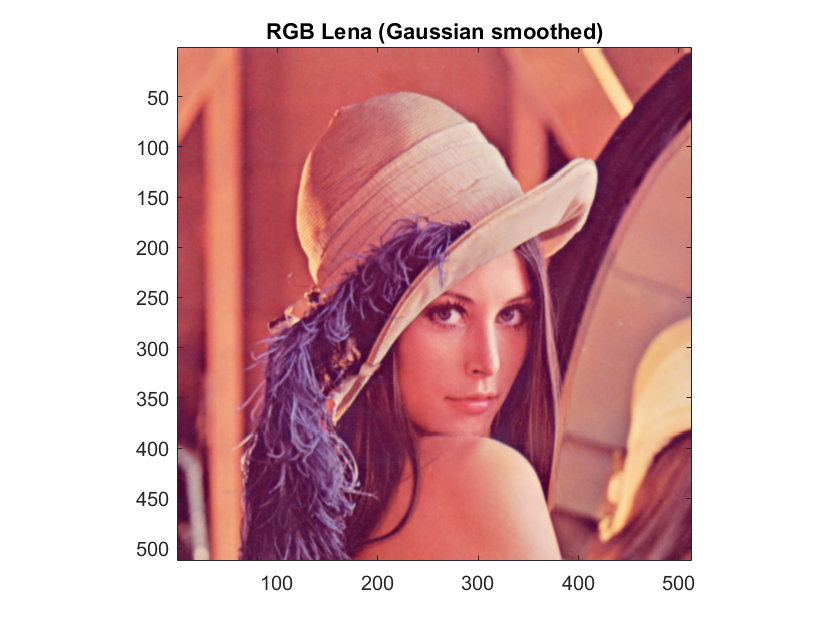

%1
B = imgaussfilt (A, 0.7);
image(B); 
axis image;
title('RGB Lena (Gaussian smoothed)');

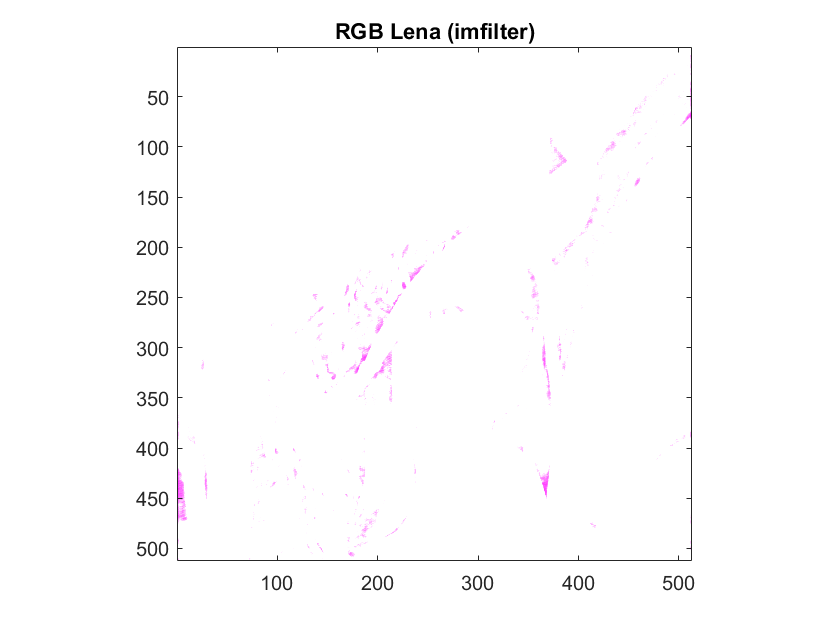


% 2
h = [1 2 4; 4 1 0; 0 1 2]; % Using kernel 
K = imfilter(A,h);
image(K); 
axis image;
title('RGB Lena (imfilter)');

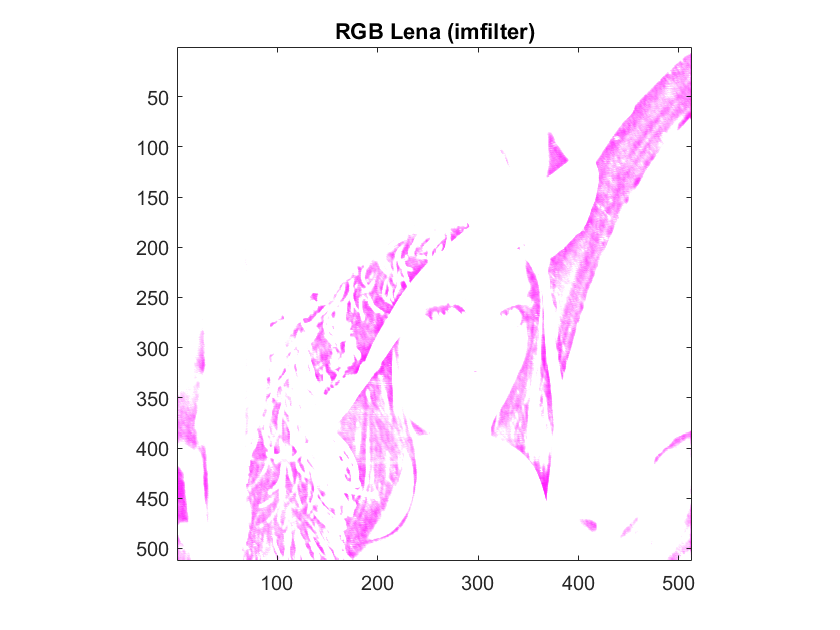


% 3
h = [1 1 1; 0 1 0; 0 1 2]; % Using kernel
K = imfilter(A,h);
image(K); 
axis image;
title('RGB Lena (imfilter)');

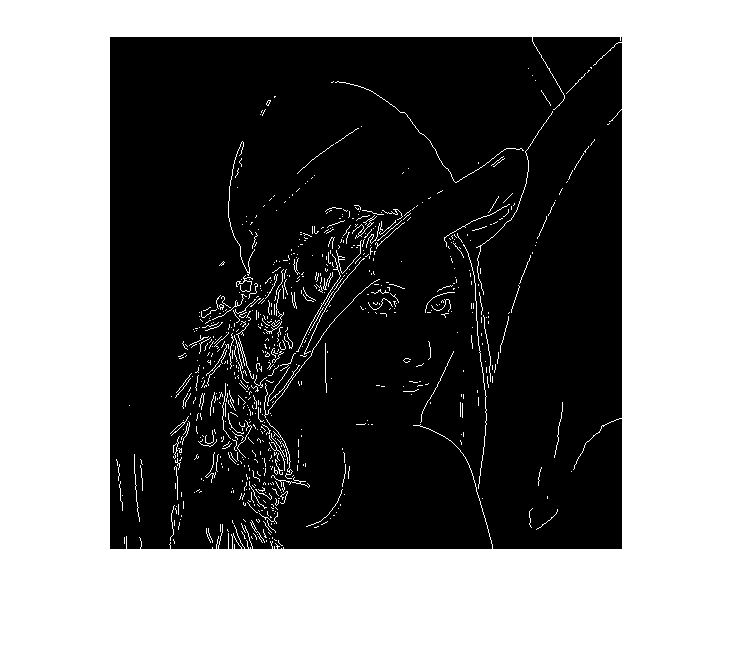


% 4
X = rgb2gray(A);
edge(X);

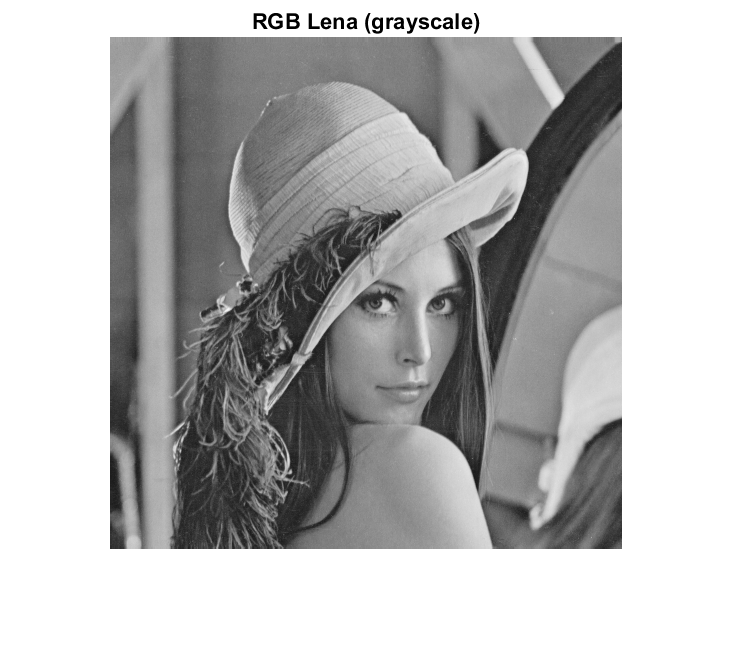

imshow(X);
axis image;
title('RGB Lena (grayscale)');

edge(X); 

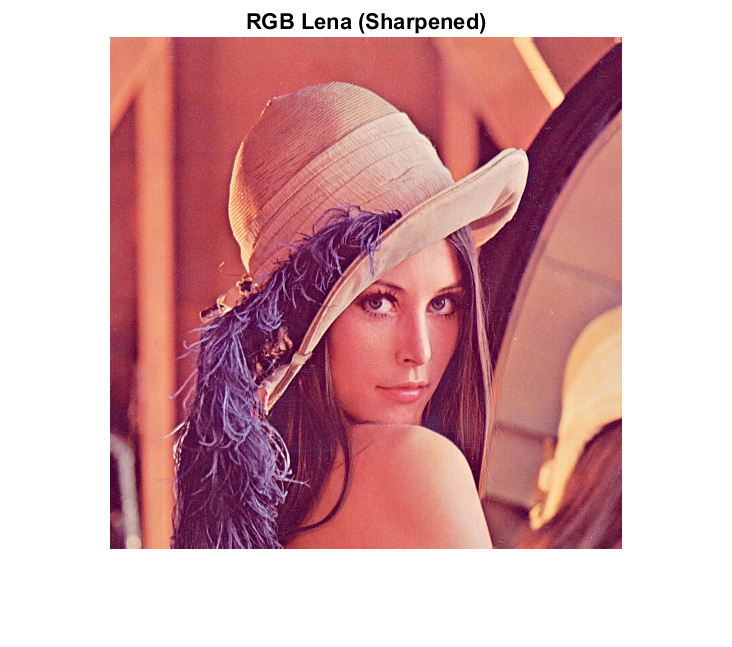


% 5
Y = imsharpen(A); 
imshow(Y);
title('RGB Lena (Sharpened)');